# **batch_run_pca_temporal**

run PCA on segmented SPA EEG data, implementing ERP appropriate PCA

author: Gerardo Parra, last updated: 2023-02-21

%eeglab;
clear

## inputs

### loading data

P.task    = get_task('tss'); 
path.tag  = '_25hzLP_32hzNF';
path.eeg  = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed',  ...
                       'EEG','Participant_Data','03_Processed_Data' );
path.task = fullfile( path.eeg,P.task.path );
path.grps = fullfile( path.eeg,'01_Subject_Info_For_Processing', ...
                      'Group_Assignments.mat' );
group     = struct('name',{'TD','ASD','SPC'});

### processing params

P.chan.incl = 1:129; %[load_1020_chans() 29 35 110 111]; %; %
P.chan.excl_1020 = [9 17 22 33 45 58 70 75 83 96 108];
P.chan.excl_all  = [1 125 8 14 126 127 21 25 32 128 38   ...
                    43 48 44 49 56 57 63 64 68 69 73 74  ...
                    81 82 88 89 94 95 99 100 107 113 114 ...
                    120 119 121];
P.chan.excl = [P.chan.excl_all]; %P.chan.excl_1020] %
P.chan.pca  = setdiff(P.chan.incl,P.chan.excl); % channels to run PCA on
P.chan.plot = [36];       % channels to base plots on
P.t.win     = [-50 600];  % time window (ms) to use in PCA, [] to use all
P.t.rsamp   = 10;         % factor to resample time series by
P.pca.by_group     = false; % 1 = run separate PCAs by group, 0 = single PCA
P.plot.indiv_score = false; % 1 = plot individuals scores for 5 random subjects
P.plot.colors  = {'#4444c9','#217538','#db4214'};
P.plot.markers = {'o','+','*'};

## load data

[DATA,FPI,P.t.times,P.t.seg_win,P.t.Fs] = load_eeg_into_struct(path);

### create observation matrices

EEG = struct('data',[],'mean',[],'n',[]);
if P.pca.by_group
    n.group = max([DATA.group]);
    for i_g = 1:n.group
        % create 4d matrix: channels x samples x conditions x subjects
        EEG(i_g).ids = find([DATA.group]==i_g);
        A = cat(4,DATA(EEG(i_g).ids).eeg);
        EEG(i_g).mean = squeeze(mean(A,4));
        EEG(i_g).n = size(A,4); EEG(i_g).group = group.name{i_g};
        % prep for pca: samples x channels x subjects x conditions
        EEG(i_g).data = permute(A,[2 1 4 3]); clear A
    end
else
    % create 4d matrix: channels x samples x conditions x subjects
    A = cat(4,DATA.eeg); EEG.mean = squeeze(mean(A,4)); EEG.n = size(A,4);
    EEG.ids = 1:EEG.n;
    % prep for pca: samples x channels x subjects x conditions
    EEG.data = permute(A,[2 1 4 3]); EEG.group = 'Grand'; clear A
end
for i_g = 1:length(group), group(i_g).ids = find([DATA.group]==i_g); end
n.group = size(EEG,2); n.chan = size(EEG(1).mean,1);
n.samp  = size(EEG(1).mean,2); n.cond = size(EEG(1).mean,3);
clear DATA

## run pca

### update PCA params

if    isempty(P.t.win), P.t.ind = 1:n.samp;
else, P.t.ind = get_time_win_idxs(P.t.win,P.t.seg_win*1000,P.t.Fs);
end
P.t.n = length(P.t.ind); P.t.plot = downsample(P.t.times(P.t.ind)*1000,P.t.rsamp);
n.rsamp = ceil(P.t.n/P.t.rsamp);
P.chan.n = length(P.chan.pca); P.chan.plot_i = P.chan.pca==P.chan.plot;
P.chan.locs = FPI.net_vstruct(P.chan.pca);

### temporal pca

adapted from Scharf et al 2022

for i_g = 1:n.group
    % get matrix: observations x samples
    A = EEG(i_g).data(:,P.chan.pca,:,:);
    A = reshape(A,[n.samp P.chan.n*EEG(i_g).n*n.cond])';
    % get selected time window
    A = A(:,P.t.ind);
    % resample
    if P.t.rsamp > 1
        A = downsample(A',P.t.rsamp)';
    end
    % EKC
    [EKC.nF,EKC.L,EKC.refs] = myEKC(corr(A),size(A,1)); 
    EEG(i_g).ekc = EKC; clear EKC
    % run PCA
    EEG(i_g).pca = ep_doPCA( 'asis', 'Geomin', 0.01, 'SVD', 'COV',  ...
                             EEG(i_g).ekc.nF, A, 'C');
end
EEG = rmfield(EEG,'data');

### resort factor scores into individuals/groups

for i_g = 1:n.group    
    % reshape score: subjects x chans x conds x factor
    dims = [EEG(i_g).ekc.nF P.chan.n EEG(i_g).n n.cond];
    score = EEG(i_g).pca.FacScr; score = reshape(score',dims);
    EEG(i_g).pca.FacScrPerm = permute(score,[3 2 4 1]); clear score
end

## plot outputs

### factor loadings and scores

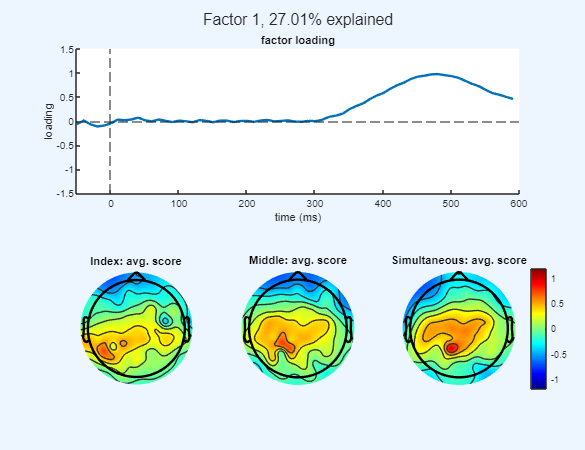

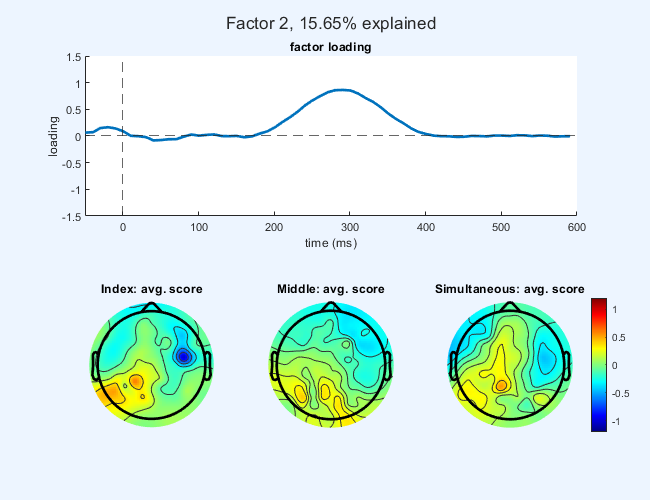

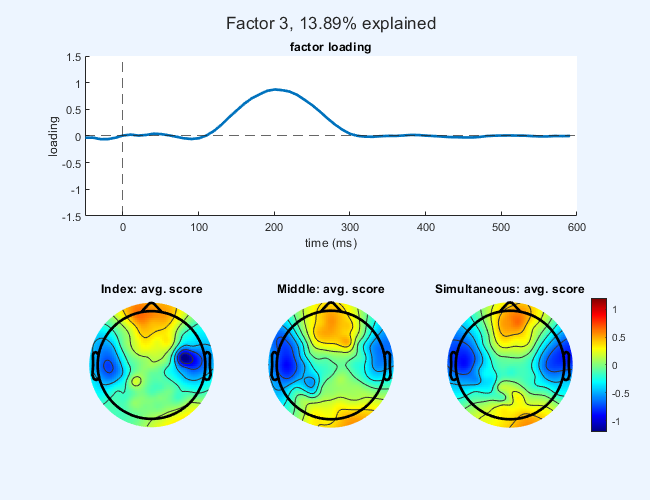

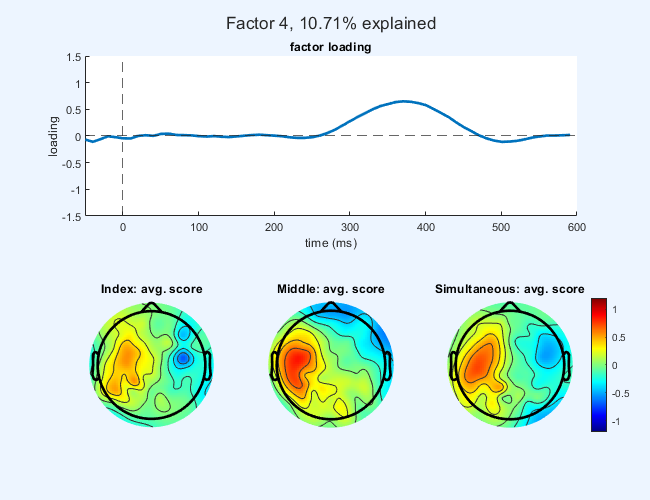

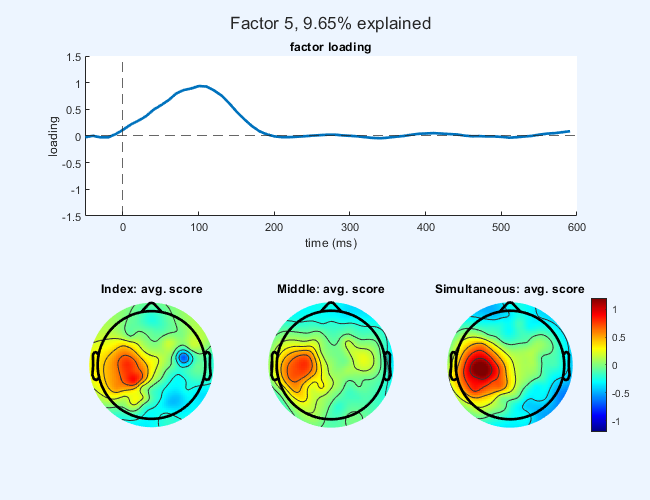

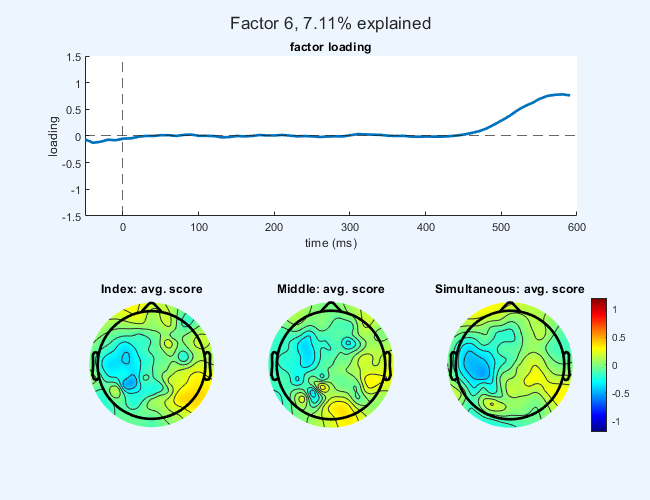

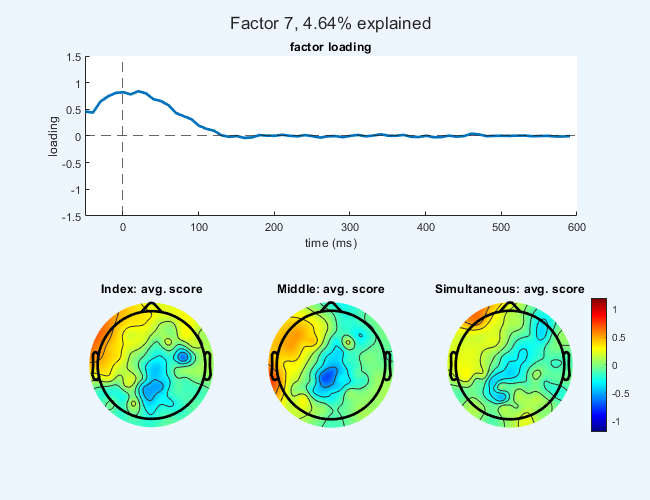

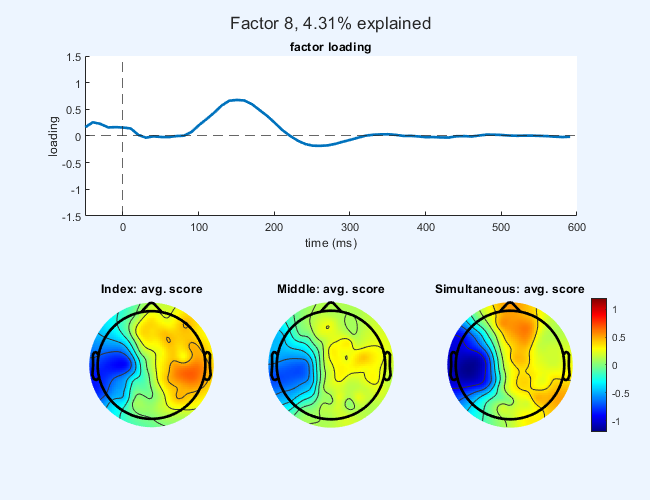

for i_g = 1:n.group
    for i_f = 1:EEG(i_g).ekc.nF
        % set up factor figure
        figure('Position',[50 100 650 500]); hold on, fac.lo = tiledlayout(2,3);
        fac.var = EEG(i_g).pca.facVar(i_f)*100;
        fac.title = sprintf('Factor %d, %.2f%% explained',i_f,fac.var);
        title(fac.lo,fac.title)
        % plot factor loading (timecourse)
        nexttile([1 3]), hold on, title('factor loading')
        plot(P.t.plot,EEG(i_g).pca.FacPat(:,i_f),'LineWidth',2)
        xline(0,'--'), yline(0,'--'), xlim(P.t.win), ylim([-1.5 1.5])
        xlabel('time (ms)'), ylabel('loading')
        % plot mean factor score (topography) for each condition
        for i_c = 1:n.cond
            cond.title = [P.task.conds{i_c} ': avg. score'];
            nexttile([1 1]), hold on, title(cond.title)
            cond.mean = squeeze(mean(EEG(i_g).pca.FacScrPerm(:,:,i_c,i_f),1));
            cond.tp = topoplot(cond.mean,P.chan.locs); caxis([-1.2 1.2])
            if i_c==n.cond, colorbar; end, clear cond
        end
        clear fac
    end
end

### suppression (from factor scores)

**note:** only works if one PCA was run on all groups together

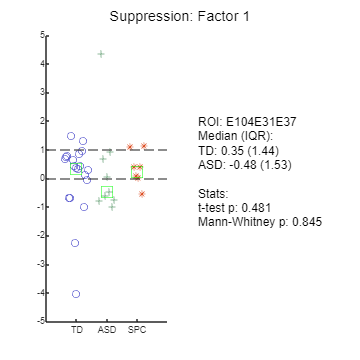

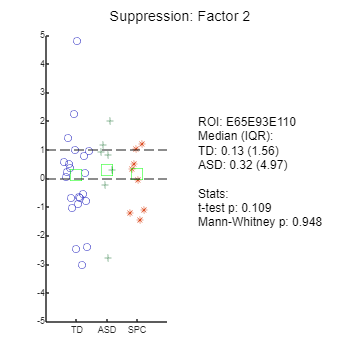

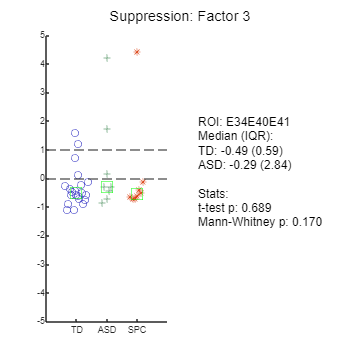

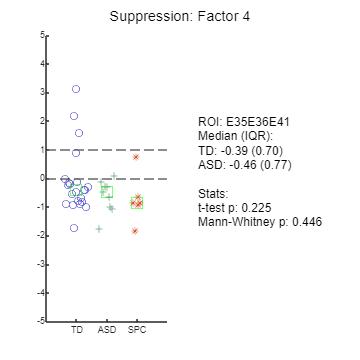

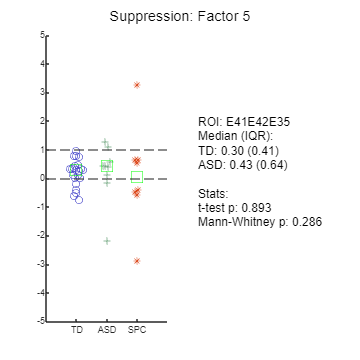

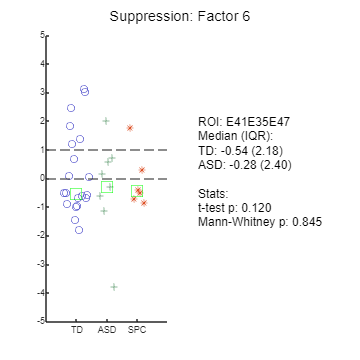

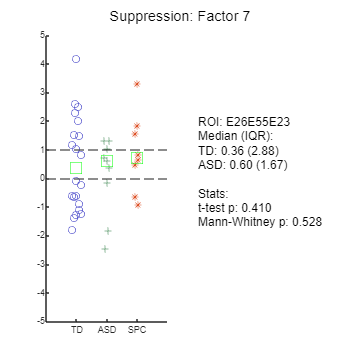

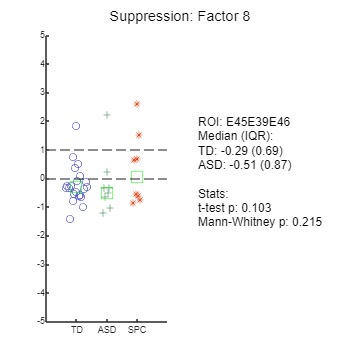

neg_comps = [4]; n_roi_chans = 3; plot_thr = [-5 5];
for i_f = 1:EEG.ekc.nF
    fac.isneg = any(i_f==neg_comps); 
    fac.field = ['SF_f' int2str(i_f)];
    % get group factor suppression fractions
    for i_g = 1:length(group)
        fac.ids = group(i_g).ids; fac.scr = squeeze(EEG.pca.FacScrPerm(fac.ids,:,:,i_f));
        % get scalpwide suppression mean across participants
        group(i_g).([fac.field '_sw']) = squeeze(mean(get_sf(fac.scr,fac.isneg),1));
        %% TODO: get individualized rois
        % get channels with highest grand average scores
        [~,fac.chans] = maxk(abs(mean(mean(fac.scr,3),1)),n_roi_chans);
        fac.scr = squeeze(mean(fac.scr(:,fac.chans,:),2));
        group(i_g).(fac.field) = get_sf(fac.scr,fac.isneg);%,plot_thr);
        group(i_g).([fac.field '_med']) = median(group(i_g).(fac.field));
        group(i_g).([fac.field '_IQR']) = iqr(group(i_g).(fac.field));
    end
    % plot suppression by group
    figure('Position',[40 200 400 400]); subplot(1,2,1)
    sgtitle(['Suppression: Factor ' int2str(i_f)])
    plotSpread({group.(fac.field)},'showMM',3,'distributionColors',P.plot.colors, ...
               'distributionMarkers',P.plot.markers)
    xticklabels({group.name}), yline([0 1],'--'), ylim(plot_thr)
    % plot stats
    [~,fac.t] = ttest2(group(1).(fac.field)',group(2).(fac.field)');
    fac.mw = ranksum(group(1).(fac.field)',group(2).(fac.field)');
    text(5,2,['ROI: ' strcat(P.chan.locs(fac.chans).labels)])
    text(5,1.5,'Median (IQR):')
    text(5,1,sprintf('TD: %0.2f (%0.2f)',group(1).([fac.field '_med']),group(1).([fac.field '_IQR'])))
    text(5,0.5,sprintf('ASD: %0.2f (%0.2f)',group(2).([fac.field '_med']),group(2).([fac.field '_IQR'])))
    text(5,-0.5,'Stats:'), text(5,-1,sprintf('t-test p: %0.3f',fac.t))
    text(5,-1.5,sprintf('Mann-Whitney p: %0.3f',fac.mw))
    clear fac
end

### suppression 3d scatter

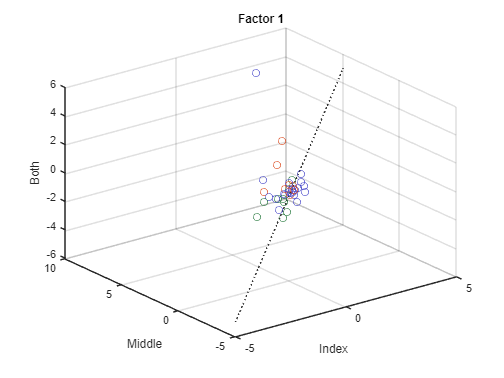

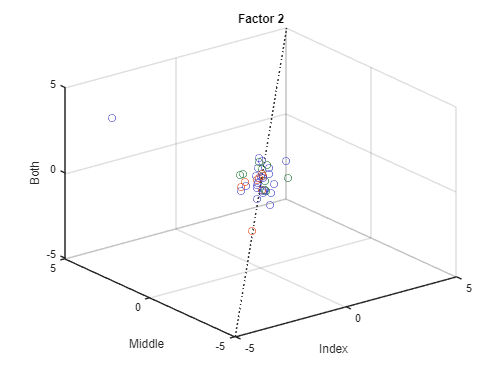

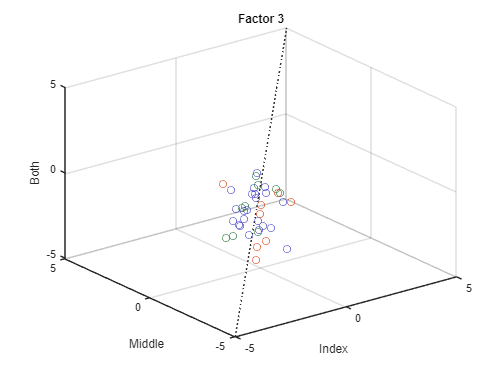

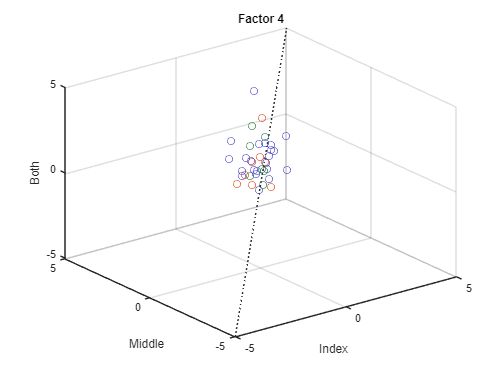

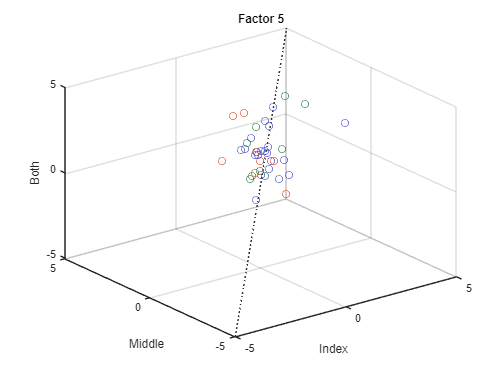

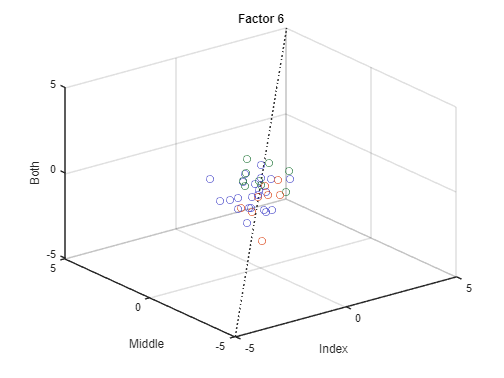

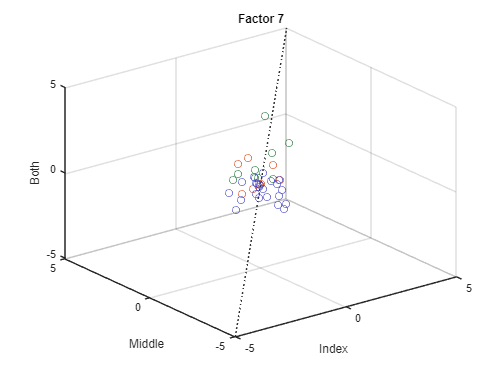

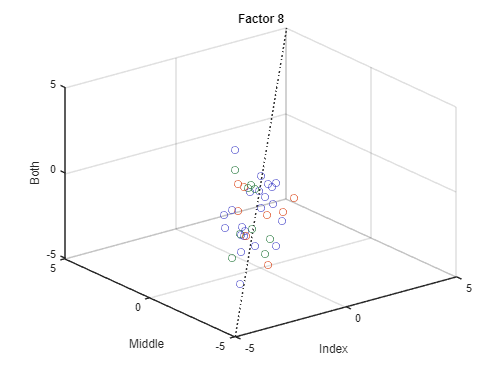

for i_f = 1:EEG.ekc.nF
    % initialize figure for factor
    fac.range = -5:5;
    figure; plot3(fac.range,fac.range,fac.range,':','Color','#333'); hold on; grid on; 
    title(['Factor ' int2str(i_f)]); xlabel('Index'), ylabel('Middle'), zlabel('Both')
    % get group factor suppression fractions
    for i_g = 1:length(group)
        fac.ids = group(i_g).ids; fac.scr = squeeze(EEG.pca.FacScrPerm(fac.ids,:,:,i_f));
        % get channels with highest grand average scores
        [~,fac.chans] = maxk(abs(mean(mean(fac.scr,3),1)),n_roi_chans);
        fac.scr = squeeze(mean(fac.scr(:,fac.chans,:),2));
        scatter3(fac.scr(:,1),fac.scr(:,2),fac.scr(:,3),'MarkerEdgeColor',P.plot.colors{i_g})
    end
end

clear fac

### scalp-wide suppression by group

% for i_f = 1:EEG.ekc.nF
%     fac.field = ['SF_f' int2str(i_f) '_sw'];
%     figure('Position',[400 200 900 300]); fac.tl = tiledlayout(1,3);
%     title(fac.tl,sprintf('Factor %d Mean Suppression',i_f))
%     for i_g = 1:length(group)
%         nexttile([1 1]); title(group(i_g).name)
%         fac.tp = topoplot(group(i_g).(fac.field),P.chan.locs); caxis([-1 1])
%         if i_g==length(group), colorbar; end
%     end
%     clear fac
% end

### selected factor score sums, for random individuals

if P.plot.indiv_score

% select factors to plot summed scores for
P.pca.fac_ind = [4];
for i_g = 1:n.group
    figure('Position',[250 0 700 1000]); grp.lo = tiledlayout(6,3); 
    grp.title = ['Average score, Factors: ' int2str(P.pca.fac_ind)];
    title(grp.lo,grp.title)
    % plot grand average across selected factors
    grp.fac_sum = mean(sum(EEG(i_g).pca.FacScrPerm(:,:,:,P.pca.fac_ind),4),1);
    for i_c = 1:n.cond
        nexttile([1 1]); hold on, title(P.task.conds{i_c}); caxis([-1 1])
        grp.tp = topoplot( squeeze(grp.fac_sum(:,:,i_c)), P.chan.locs ); 
    end
    % plot 6 random individuals
    P.randi = randsample(1:EEG(i_g).n,5);
    for i_r = P.randi
        subj.title = [int2str(DATA(i_r).id) ', ' group(DATA(i_r).group).name];
        subj.fac_sum = sum(EEG(i_g).pca.FacScrPerm(i_r,:,:,P.pca.fac_ind),4);
        for i_c = 1:n.cond
            nexttile([1 1]); hold on, caxis([-1 1])
            if i_c == round(n.cond/2), title(subj.title); end
            subj.tp = topoplot( squeeze(subj.fac_sum(:,:,i_c)),P.chan.locs );
        end
    end
    clear grp subj
end

end

## helper functions

function SF = get_sf(cond_scr,neg_comp,thr_data)
    % returns suppression fraction for nx3 array
    % handle negative components
    if ~exist('neg_comp','var'), neg_comp = 0; end
    if neg_comp, cond_scr = -1 * cond_scr; end
    % SF = (IM-B)/IM
    if ndims(cond_scr) == 3
        i = cond_scr(:,:,1); m = cond_scr(:,:,2); b = cond_scr(:,:,3);
        im = i+m; SF = (im-b)./im; 
        % potentially very high values where factor score for >=1 condition
        % is very low. threshold for extreme SF
        SF(abs(SF)>5) = 0;
    else
        i = cond_scr(:,1); m = cond_scr(:,2); b = cond_scr(:,3);
        im = i+m; SF = (im-b)./im;
    end
    % negate if I+M<0
    SF(im<0) = -1*SF(im<0);
    % threshold data for plots
    if exist('thr_data','var')
        if thr_data ~= 0
            SF(SF > thr_data(2)) = thr_data(2);
            SF(SF < thr_data(1)) = thr_data(1);
        end
    end
end